# ME 535 Assignment 3, Fall 2018

# Debabrata Auddya

**Question 4.3:**

**c.  Read the IGES file into Matlab**

**Name of igs file: Fish.igs**

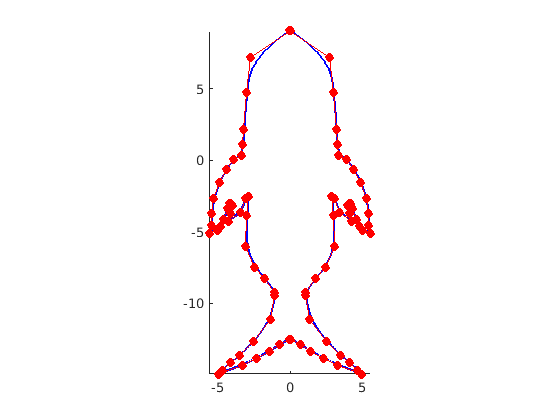

degree 3
weights
  Columns 1 through 23

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

  Columns 24 through 42

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

control points...
    0.0600    9.0265         0
    2.7841    7.1406         0
    3.0355    4.7518         0
    3.2451    2.1115         0
    3.2870    1.1057         0
    3.4127    0.3094         0
    3.9575    0.0580         0
    4.4604   -0.6545         0
    4.9214   -1.5346         0
    5.3405   -2.6661         0
    5.4662   -3.7138         0
    5.4662   -4.5520         0
    5.5919   -5.1387         0
    5.0890   -4.8873         0
    4.8795   -4.6358         0
    4.6700   -4.1748         0
    4.3347   -3.3785         0
    4.2090   -3.0433         0
    4.1670   -3.0433         0
    3.9994   -3.1690         0
    4.1251   -3.7557         0
    4.292

% read the igs file to matlab
clear;clf;
file_name = input('Pleas input the file name: ','s');
fp = fopen(file_name, 'r');
s = fscanf(fp,'%c',[82 inf]);s=s';
fclose(fp);

n=size(s);
j=0;
for i=1:n(1)-1
    temp = s(i,:);
    t = str2double(temp(6:8));
    % If t=126 indicate this line recorded a BS_curve
    if t == 126
        j = j+1;
        % find the bs_curve parameter segment number
        l = temp(13:16);
        % the following find BS_curve parameter segment
        for ii = i:n(1)-1
            temp1 = s(ii,:);
            % find BSCURVE parameter segment
            if strcmp(temp1(77:80),l) & str2double(temp1(1:3)) == t
                % parameter segment sign, in our example is '21P'
                temp2 = temp1(70:73);
                row1 = ii;
                for i2 = ii:n(1)-1
                    temp3 = s(i2,:);
                    % find all parameter lines in the same BSCURVE
                    if strcmp(temp3(70:73),temp2)
                        % record the last BS_curve parameter line
                        k = i2;
                    end
                end
                for i3=1:k-row1+1
                    bs(i3,:)=s(row1+i3-1,:);
                end
                %call bspline processing function
                hold on;
                bsp_curve(bs);
                clear bs
            end
        end
    elseif t==128 %  BS_surface
        j=j+1;
        l = temp(13:16);%bs_surface eparameter segment
        %  find bs_surface parameter
        for ii=i:n(1)-1
            temp1=s(ii,:);
           if strcmp(temp1(77:80),l) & str2double(temp1(1:3)) == t% find BSCURVE parameter segment
                % parameter segment example: 25p
                temp2 = temp1(70:73);
                row1=ii;
                for i2=ii:n(1)-1
                    temp3=s(i2,:);
                    % find all parameter lines in the same BSCURVE
                    if strcmp(temp3(70:73),temp2)
                        k=i2; %record the last BS_cruve parameter line
                    end
                end
                for i3=1:k-row1+1
                    bs(i3,:)=s(row1+i3-1,:);
                end
                %call bs drawing function
                hold on;
                bsp_surface(bs);
                view(-8,-42);
                clear bs
            end
        end
    end
    
end